clc, clf, clear
addpath('Data\')
addpath('..\own-pt-assist\')
%good1 = ParseMatlabAppFinal('GPaloft1');
f_good1 = move_avg_filt(ParseMatlabAppFinal('GPaloft1'), 7);
f_good2 = move_avg_filt(ParseMatlabAppFinal('GPaloft2'), 7);
f_good3 = move_avg_filt(ParseMatlabAppFinal('GPaloft3'), 7);
f_good4 = move_avg_filt(ParseMatlabAppFinal('GPaloft4'), 7);

good1 = fft_from_time(f_good1, 10);
good2 = fft_from_time(f_good2, 10);
good3 = fft_from_time(f_good3, 10);
good4 = fft_from_time(f_good4, 10);

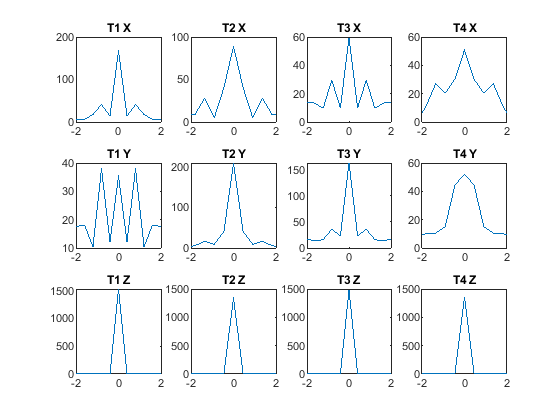

clf
figure();
subplot(3,4,1)
plot(good1(:,1), abs(good1(:,2)))
xlim([-2 2])
title('T1 X')
subplot(3,4,2)
plot(good2(:,1), abs(good2(:,2)))
xlim([-2 2])
title('T2 X')
subplot(3,4,3)
plot(good3(:,1), abs(good3(:,2)))
xlim([-2 2])
title('T3 X')
subplot(3,4,4)
plot(good4(:,1), abs(good4(:,2)))
xlim([-2 2])
title('T4 X')

subplot(3,4,5)
plot(good1(:,1), abs(good1(:,3)))
xlim([-2 2])
title('T1 Y')
subplot(3,4,6)
plot(good2(:,1), abs(good2(:,3)))
xlim([-2 2])
title('T2 Y')
subplot(3,4,7)
plot(good3(:,1), abs(good3(:,3)))
xlim([-2 2])
title('T3 Y')
subplot(3,4,8)
plot(good4(:,1), abs(good4(:,3)))
xlim([-2 2])
title('T4 Y')

subplot(3,4,9)
plot(good1(:,1), abs(good1(:,4)))
xlim([-2 2])
title('T1 Z')
subplot(3,4,10)
plot(good2(:,1), abs(good2(:,4)))
xlim([-2 2])
title('T2 Z')
subplot(3,4,11)
plot(good3(:,1), abs(good3(:,4)))
xlim([-2 2])
title('T3 Z')
subplot(3,4,12)
plot(good4(:,1), abs(good4(:,4)))
xlim([-2 2])
title('T4 Z')

f_bad1 = move_avg_filt(ParseMatlabAppFinal('BInArcPaloft1'), 7);
f_bad2 = move_avg_filt(ParseMatlabAppFinal('BInArcPaloft2'), 7);
f_bad3 = move_avg_filt(ParseMatlabAppFinal('BInArcPaloft3'), 7);
f_bad4 = move_avg_filt(ParseMatlabAppFinal('BInArcPaloft4'), 7);

bad1 = fft_from_time(f_bad1, 10);
bad2 = fft_from_time(f_bad2, 10);
bad3 = fft_from_time(f_bad3, 10);
bad4 = fft_from_time(f_bad4, 10);

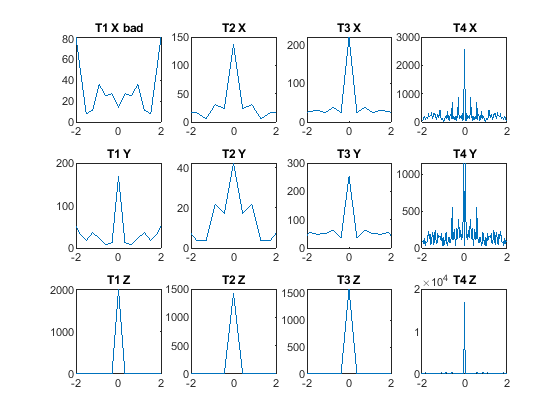

clf
figure();
subplot(3,4,1)
plot(bad1(:,1), abs(bad1(:,2)))
xlim([-2 2])
title('T1 X bad')
subplot(3,4,2)
plot(bad2(:,1), abs(bad2(:,2)))
xlim([-2 2])
title('T2 X')
subplot(3,4,3)
plot(bad3(:,1), abs(bad3(:,2)))
xlim([-2 2])
title('T3 X')
subplot(3,4,4)
plot(bad4(:,1), abs(bad4(:,2)))
xlim([-2 2])
title('T4 X')

subplot(3,4,5)
plot(bad1(:,1), abs(bad1(:,3)))
xlim([-2 2])
title('T1 Y')
subplot(3,4,6)
plot(bad2(:,1), abs(bad2(:,3)))
xlim([-2 2])
title('T2 Y')
subplot(3,4,7)
plot(bad3(:,1), abs(bad3(:,3)))
xlim([-2 2])
title('T3 Y')
subplot(3,4,8)
plot(bad4(:,1), abs(bad4(:,3)))
xlim([-2 2])
title('T4 Y')

subplot(3,4,9)
plot(bad1(:,1), abs(bad1(:,4)))
xlim([-2 2])
title('T1 Z')
subplot(3,4,10)
plot(bad2(:,1), abs(bad2(:,4)))
xlim([-2 2])
title('T2 Z')
subplot(3,4,11)
plot(bad3(:,1), abs(bad3(:,4)))
xlim([-2 2])
title('T3 Z')
subplot(3,4,12)
plot(bad4(:,1), abs(bad4(:,4)))
xlim([-2 2])
title('T4 Z')

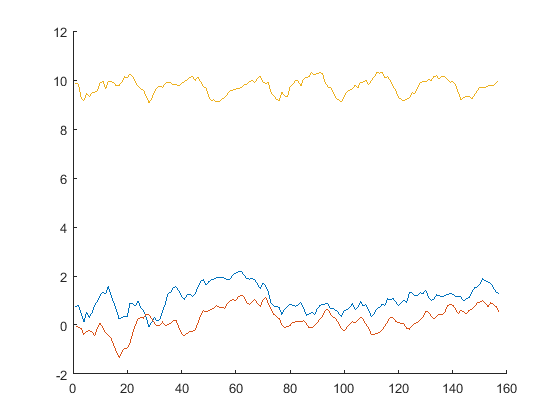

clf
hold on
plot(f_good1(:,1))
plot(f_good1(:,2))
plot(f_good1(:,3))